imds = imageDatastore('C:\Users\shitosu\Desktop\image200', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames')

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');
augimdsTrain = augmentedImageDatastore([224,224],imdsTrain);
augimdsValid = augmentedImageDatastore([224,224],imdsValidation);


layers = [
    imageInputLayer([224 224 3], 'Name', 'input')

    convolution2dLayer(9, 24, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'batchnorm1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(4, 'Stride', 4, 'Name', 'maxpool1')

    convolution2dLayer(5, 48, 'Padding', 'same', 'Name', 'conv2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer(4, 'Stride', 4, 'Name', 'maxpool2')

    convolution2dLayer(3, 48, 'Padding', 'same', 'Name', 'conv3')
    batchNormalizationLayer('Name', 'batchnorm2')
    reluLayer('Name', 'relu3')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool3')

    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu4')
    fullyConnectedLayer(8, 'Name', 'fc2')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')];
lgraph = layerGraph(layers);


options = trainingOptions('adam', 'ValidationData',augimdsValid,'ValidationFrequency',10,'InitialLearnRate', 0.001, 'MaxEpochs', 10, 'MiniBatchSize', 32,Plots='training-progress');

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |        6.25% |       14.17% |       4.0672 |       3.7733 |          0.0010 |
|       1 |          10 |       00:00:11 |       21.88% |       21.46% |       2.0875 |       2.0089 |          0.0010 |
|       1 |          20 |       00:00:17 |       46.88% |       27.08% |       1.7586 |       1.9034 |          0.0010 |
|       1 |          30 |       00:00:22 |       31.25% |       38.33% |       1.8195 |   

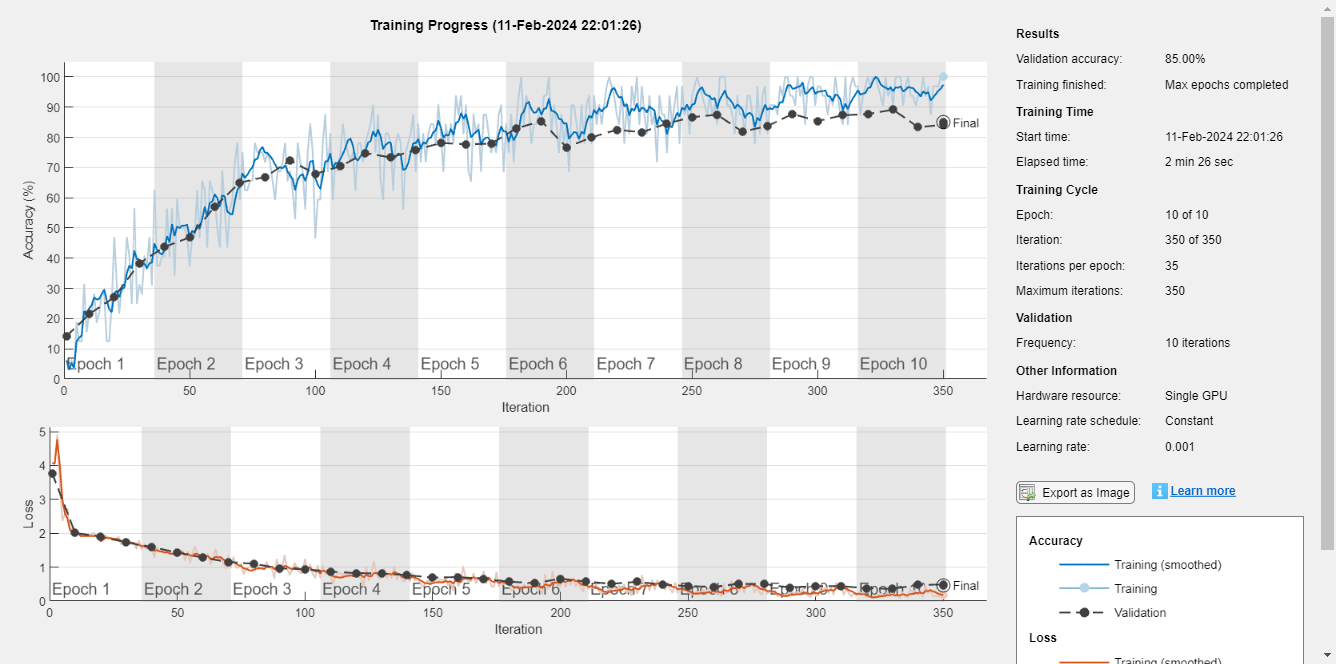

model =   DAGNetwork with properties:

         Layers: [17×1 nnet.cnn.layer.Layer]
    Connections: [16×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


info = struct with fields:
               TrainingLoss: [4.0672 4.0608 4.9027 3.4986 2.3754 2.5658 2.7182 2.0769 2.1734 2.0875 2.0362 1.9184 1.9559 1.9463 1.9805 1.9579 2.0044 1.9707 1.9313 1.7586 1.9422 1.9236 1.8632 1.8387 1.7907 1.8244 1.8901 1.6738 1.7500 … ] (1×350 double)
           TrainingAccuracy: [6.2500 3.1250 6.2500 3.1250 18.7500 12.5000 12.5000 31.2500 15.6250 21.8750 21.8750 28.1250 18.7500 21.8750 28.1250 28.1250 12.5000 12.5000 25 46.8750 31.2500 21.8750 31.2500 31.2500 46.8750 40.6250 25 … ] (1×350 double)
             ValidationLoss: [3.7733 NaN NaN NaN NaN NaN NaN NaN NaN 2.0089 NaN NaN NaN NaN NaN NaN NaN NaN NaN 1.9034 NaN NaN NaN NaN NaN NaN NaN NaN NaN 1.7318 NaN NaN NaN NaN NaN NaN NaN NaN NaN 1.5978 NaN NaN NaN NaN NaN NaN NaN … ] (1×350 double)
         ValidationAccuracy: [14.1667 NaN NaN NaN NaN NaN NaN NaN NaN 21.4583 NaN NaN NaN NaN NaN NaN NaN NaN NaN 27.0833 NaN NaN NaN NaN NaN NaN NaN NaN NaN 38.3333 NaN NaN NaN NaN NaN NaN NaN NaN NaN 43.7500 NaN NaN 


[model, info] = trainNetwork(augimdsTrain, lgraph, options)


disp(model.Layers)

  17×1 Layer array with layers:

     1   'input'        Image Input             224×224×3 images with 'zerocenter' normalization
     2   'conv1'        2-D Convolution         24 9×9×3 convolutions with stride [1  1] and padding 'same'
     3   'batchnorm1'   Batch Normalization     Batch normalization with 24 channels
     4   'relu1'        ReLU                    ReLU
     5   'maxpool1'     2-D Max Pooling         4×4 max pooling with stride [4  4] and padding [0  0  0  0]
     6   'conv2'        2-D Convolution         48 5×5×24 convolutions with stride [1  1] and padding 'same'
     7   'relu2'        ReLU                    ReLU
     8   'maxpool2'     2-D Max Pooling         4×4 max pooling with stride [4  4] and padding [0  0  0  0]
     9   'conv3'        2-D Convolution         48 3×3×48 convolutions with stride [1  1] and padding 'same'
    10   'batchnorm2'   Batch Normalization     Batch normal

% Saving training info
save('Qmodel_info.mat',"info")

Saving model

save('Qmodel.mat', 'model');


Evaluation

predictions = classify(model, augimdsValid);
trueLabels = imdsValidation.Labels;
C = confusionmat(trueLabels, predictions);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C)

    40     3     1     2     1     3    10     0
     0    60     0     0     0     0     0     0
     0     1    50     2     0     5     2     0
     0     0     2    48     8     2     0     0
     0     0     0     0    60     0     0     0
     2     0     3     0     0    50     5     0
     1     0     0     2     3     1    53     0
     0     3     3     0     0     6     1    47



figure;
% Instead of uniqueA input number of classes used for training
confusionchart(C, uniqueA, 'Normalization', 'row-normalized', 'RowSummary', 'row-normalized');

Error using confusionchart
Confusion matrix and labels must have the same number of classes.

title('Confusion Matrix');

Training and Validation PLOTS 

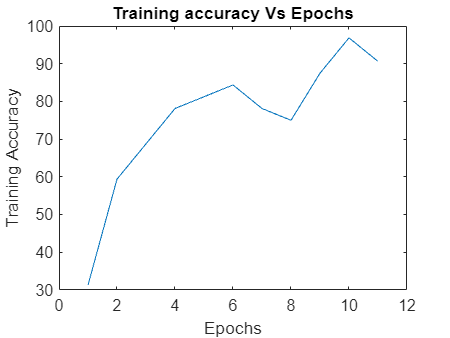

plot(info.TrainingAccuracy(30:30:end))
title('Training accuracy Vs Epochs')
ylabel("Training Accuracy")
xlabel("Epochs")

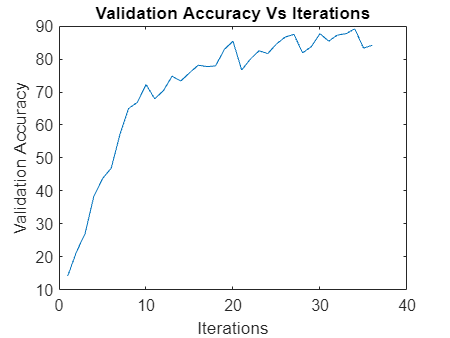

plot(info.ValidationAccuracy(~isnan(info.ValidationAccuracy)))
title('Validation Accuracy Vs Iterations')
xlabel('Iterations')
ylabel('Validation Accuracy')

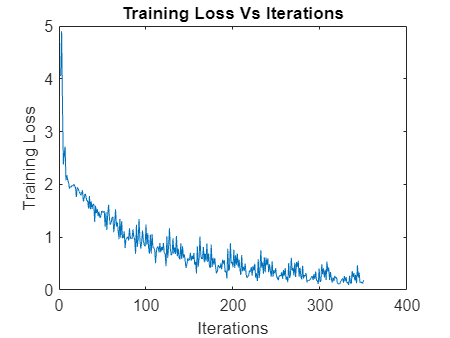

plot(info.TrainingLoss)
title("Training Loss Vs Iterations")
xlabel('Iterations')
ylabel('Training Loss')

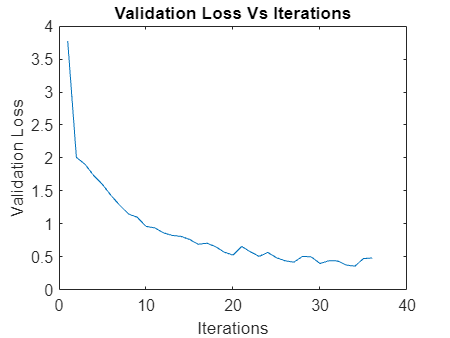

plot(info.ValidationLoss(~isnan(info.ValidationLoss)))
title('Validation Loss Vs Iterations')
xlabel('Iterations')
ylabel('Validation Loss')

Precision Recall

TP = diag(C)  % True positives are on the diagonal

TP =     40
    60
    50
    48
    60
    50
    53
    47


FP = sum(C, 1)' - TP % False positives are the sum of each column minus the true positives

FP =      3
     7
     9
     6
    12
    17
    18
     0


FN = sum(C, 2) - TP % False negatives are the sum of each row minus the true positives

FN =     20
     0
    10
    12
     0
    10
     7
    13


precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
mean_precision=sum(precision)/8

mean_precision = 0.8610

mean_recall=sum(recall)/8

mean_recall = 0.8500